## Exercici Laberint

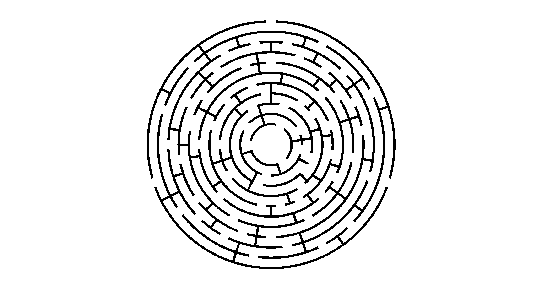

I = rgb2gray(imread('maze.png'));
BW = I > 128;
imshow(BW);

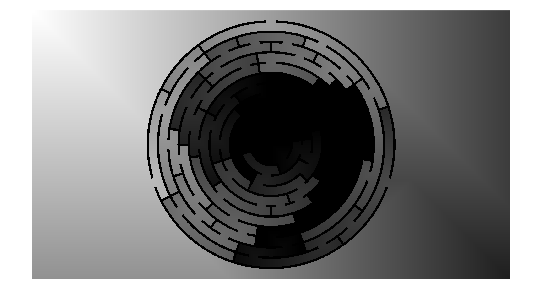

J = false(size(BW));
J(1,1) = 1;
DTG = false(size(BW));
while not(J(562, 1000))
    DTG = DTG + J;
    J = imdilate(J,ones(3,3)) & BW;
end
imshow(DTG, []);

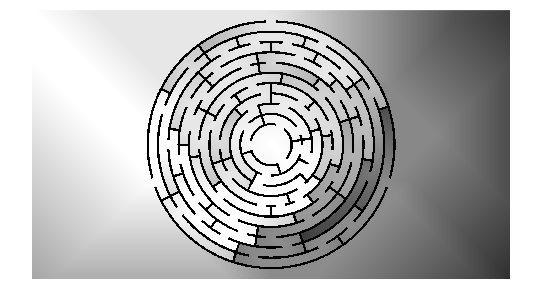


J = false(size(BW));
J(562,1000) = 1;
fi = false;
DTG2 = false(size(BW));
while not(J(1, 1))
    DTG2 = DTG2 + J;
    J = imdilate(J,ones(3,3)) & BW;
end
imshow(DTG+DTG2, []);

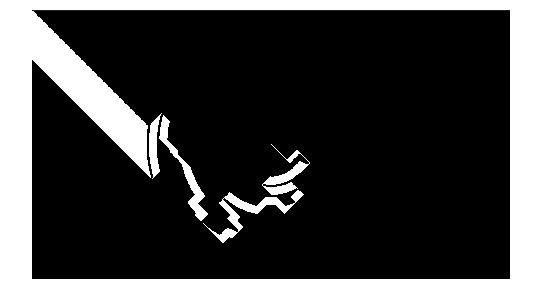

R = (DTG+DTG2) > (DTG(1,1)) - 1;
imshow(R);

## Mitjançant distancia geodèsica ja implementada

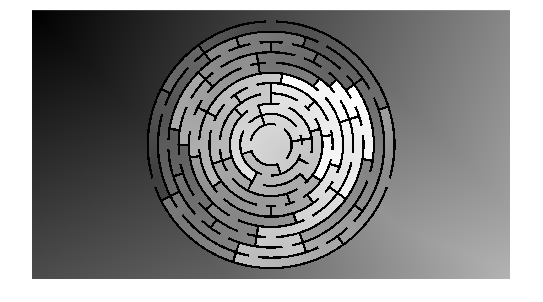

L = I > 128;
[f,c] = size(L);
D = false(size(L));
D(1,1) = 1;
DTG = bwdistgeodesic(L,D,'quasi-euclidean');
imshow(DTG, []);

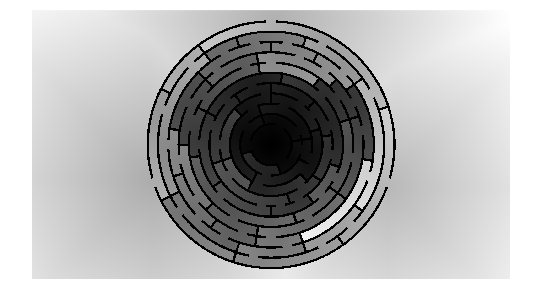


D = false(size(L));
D(562,1000) = 1;
DTG2 = bwdistgeodesic(L,D,'quasi-euclidean');
imshow(DTG2, []);

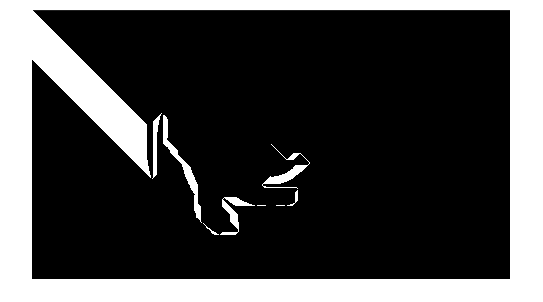


R = (DTG+DTG2 -DTG2(1,1)) < 1;
imshow(R,[]);

## Transformació esquelet

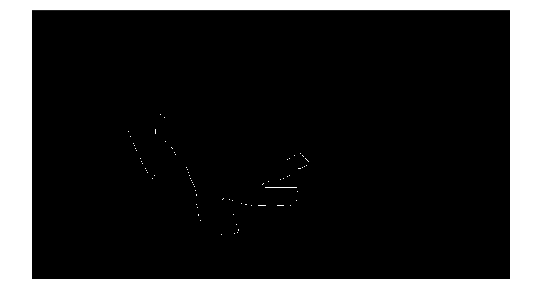

SK = bwskel(R);
imshow(SK,[]);

## Transformació skiz

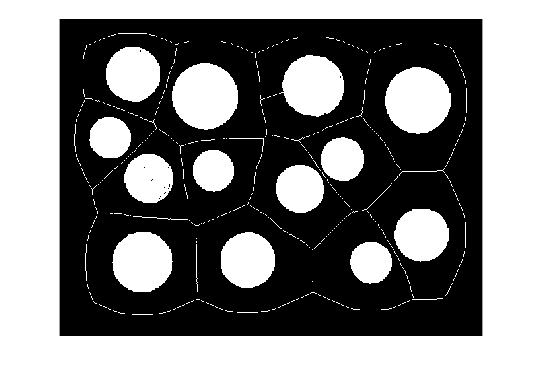

I = imread('money.tif');
BW = I > 100;
%BW = I > 90;
%BW = imclose(BW, ones(5,5));
SK = bwskel(not(BW));
imshow(SK|BW);

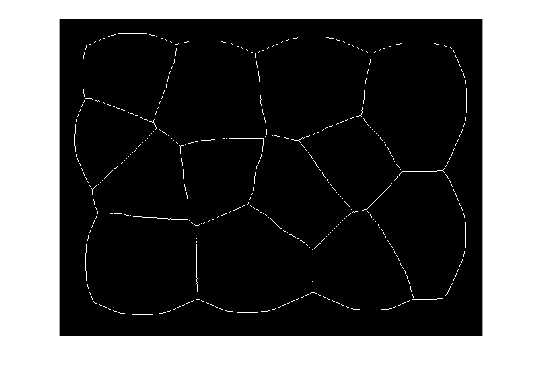

SKIZ = bwmorph(SK,'spur',Inf); % purgar branques
SKIZ = SKIZ & not(bwhitmiss(SKIZ,[-1,-1,-1;-1,1,-1;-1,-1,-1])); % eliminar píxels aïllats
imshow(SKIZ);

## Exercici trobar cèl·lula més distant respecte les altres (fora de la vora)

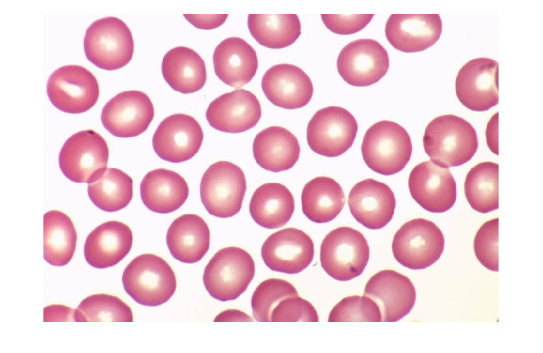

RGB = imread('normal-blood1.jpg');
imshow(RGB);

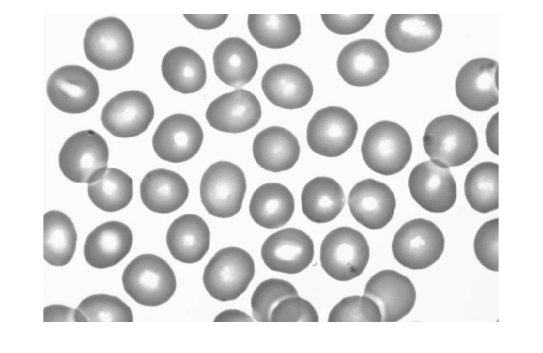

% binnarització
BW = rgb2gray(RGB);
imshow(BW);

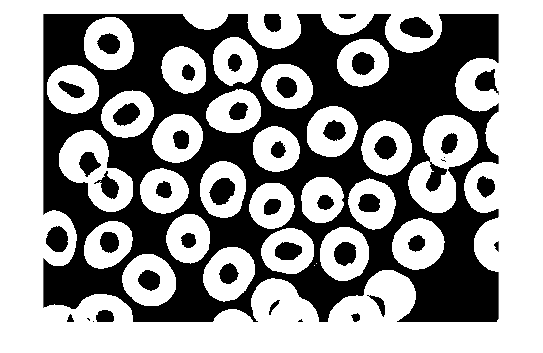

llindar = graythresh(BW);
B = BW < 255*llindar;
imshow(B);

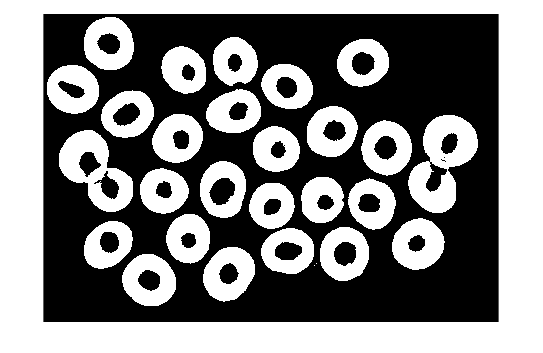

% eliminar cèl·lules de la vora
MARK = false(size(BW));
MARK(1,:) = 1;
MARK(:,1) = 1;
MARK(end,:) = 1;
MARK(:,end) = 1;
REC = imreconstruct(MARK,B,8);
C = B & not(REC);
imshow(C);

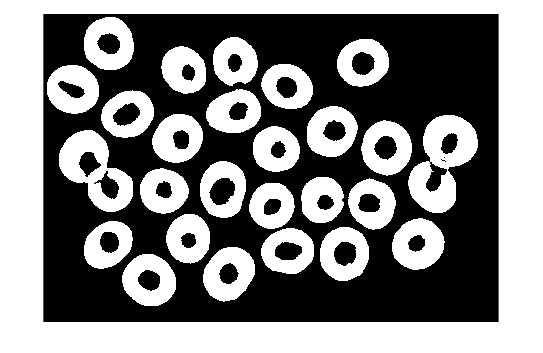

% eliminar soroll
D = bwareaopen(C,10);
% emplenar cèl·lules
ES = strel('disk',1);
E = imopen(D,ES);
imshow(E);

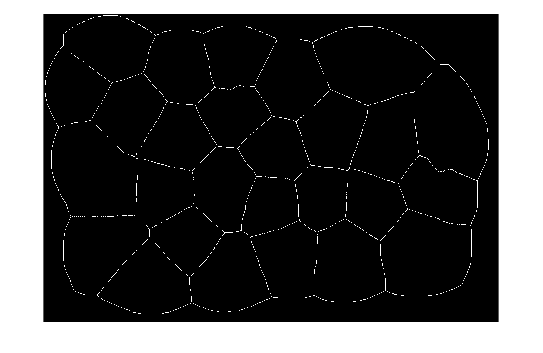

% skiz, per detectar fronteres
SK = bwskel(not(E));
SKIZ = bwmorph(SK,'spur',Inf);
SKIZ = SKIZ & not(bwhitmiss(SKIZ,[-1,-1,-1;-1,1,-1;-1,-1,-1]));
imshow(SKIZ);

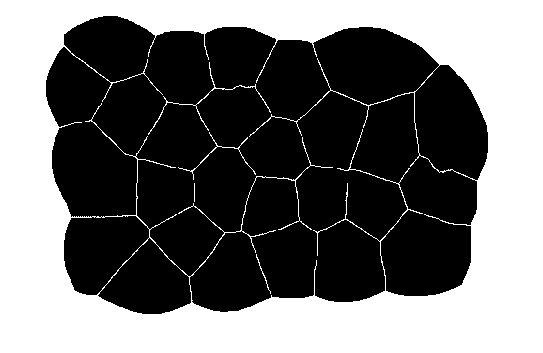

% detectar zona amb més àrea
ES = ones(2,2);
F = imdilate(SKIZ, ES);
REC = imreconstruct(MARK,not(F),8);
F = REC | F;
imshow(F);

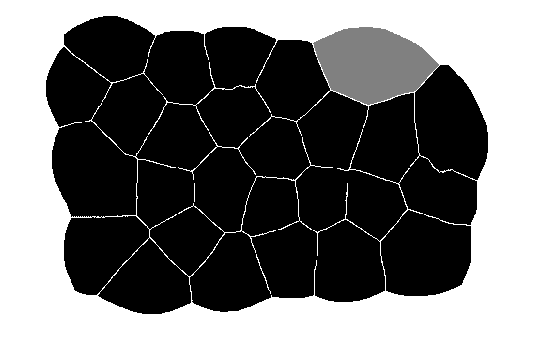

G = bwconncomp(not(F));
n_pixels = cellfun(@numel,G.PixelIdxList);
[npix, pos] = max(n_pixels);
IC = double(F);
IC(G.PixelIdxList{pos}) = 0.5;
imshow(IC);

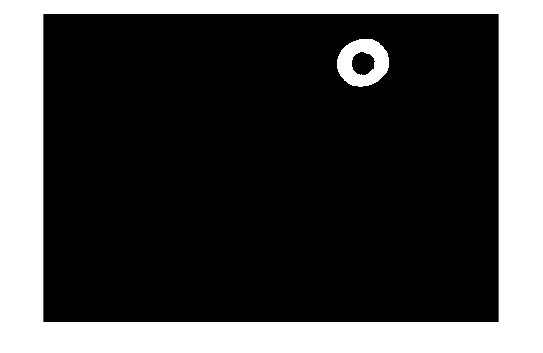

% pintar zona
K = false(size(IC));
K(IC == 0.5) = 1;
cell = K & D;
imshow(cell);

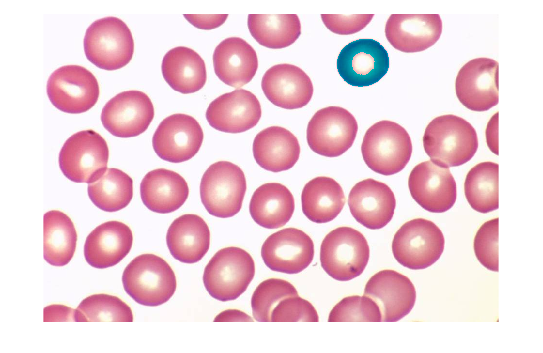

RGB(cell == 1) = 0;
imshow(RGB);